1.**Data Loading,**

2.**Task Segmentation**

The event markers in the new dataset are standardized to align with the task definitions:

disp('Third Assignment')

Third Assignment


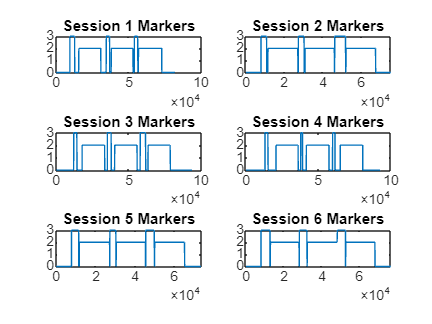


% Load the task datasets for each session
%Paths of the datasets, Change the paths for all path in this code in your
% path to coded to work professseur
data1 = load('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/Session1_Shimmer_5E8A.mat');
data2 = load('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/Session2_Shimmer_5E8A.mat');
data3 = load('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/Session3_Shimmer_5E8A.mat');
data4 = load('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/Session4_Shimmer_5E8A.mat');
data5 = load('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/Session5_Shimmer_8965.mat');
data6 = load('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/Session6_Shimmer_8965.mat');

% Function to standardize markers
function standardizedMarkers = standardizeMarkers(markers, session)
    standardizedMarkers = zeros(size(markers));
    switch session
        case {1, 2}
            for i = 1:length(markers)
                switch markers(i)
                    case 1
                        standardizedMarkers(i) = 3; % MathCalculus=3
                    case 2
                        standardizedMarkers(i) = 0; % BaseLine=0
                    case 4
                        standardizedMarkers(i) = 2; % AudioListening=2
                end
            end
        case {3, 4}
            for i = 1:length(markers)
                switch markers(i)
                    case 16
                        standardizedMarkers(i) = 2; % Listening Audio=2
                    case 4
                        standardizedMarkers(i) = 0; % Baseline=0
                    case 8
                        standardizedMarkers(i) = 3; % Math=3
                end
            end
        case {5, 6}
            for i = 1:length(markers)
                switch markers(i)
                    case 1
                        standardizedMarkers(i) = 2; % Audio=2
                    case 4
                        standardizedMarkers(i) = 0; % Baseline=0
                    case 8
                        standardizedMarkers(i) = 3; % CognLoad=3
                end
            end
    end
end

% Standardize markers for each session
data1.markers = standardizeMarkers(data1.Shimmer_5E8A_Event_Marker_CAL, 1);
data2.markers = standardizeMarkers(data2.Shimmer_5E8A_Event_Marker_CAL, 2);
data3.markers = standardizeMarkers(data3.Shimmer_5E8A_Event_Marker_CAL, 3);
data4.markers = standardizeMarkers(data4.Shimmer_5E8A_Event_Marker_CAL, 4);
data5.markers = standardizeMarkers(data5.Shimmer_8965_Event_Marker_CAL, 5);
data6.markers = standardizeMarkers(data6.Shimmer_8965_Event_Marker_CAL, 6);

% Visualize the event markers for validation
figure;
subplot(3, 2, 1); plot(data1.markers); title('Session 1 Markers');
subplot(3, 2, 2); plot(data2.markers); title('Session 2 Markers');
subplot(3, 2, 3); plot(data3.markers); title('Session 3 Markers');
subplot(3, 2, 4); plot(data4.markers); title('Session 4 Markers');
subplot(3, 2, 5); plot(data5.markers); title('Session 5 Markers');
subplot(3, 2, 6); plot(data6.markers); title('Session 6 Markers');


% Initialize the combined struct array with all fields to avoid dissimilar structures
CLData = repmat(struct('GSRraw', [], 'PPGraw', [], 'GSRPPGmarker', []), 6, 1);

% Fill in the data for the sessions
CLData(1).GSRraw = data1.Shimmer_5E8A_GSR_Skin_Conductance_CAL;
CLData(1).PPGraw = data1.Shimmer_5E8A_PPG_A13_CAL;
CLData(1).GSRPPGmarker = data1.markers;

CLData(2).GSRraw = data2.Shimmer_5E8A_GSR_Skin_Conductance_CAL;
CLData(2).PPGraw = data2.Shimmer_5E8A_PPG_A13_CAL;
CLData(2).GSRPPGmarker = data2.markers;

CLData(3).GSRraw = data3.Shimmer_5E8A_GSR_Skin_Conductance_CAL;
CLData(3).PPGraw = data3.Shimmer_5E8A_PPG_A13_CAL;
CLData(3).GSRPPGmarker = data3.markers;

CLData(4).GSRraw = data4.Shimmer_5E8A_GSR_Skin_Conductance_CAL;
CLData(4).PPGraw = data4.Shimmer_5E8A_PPG_A13_CAL;
CLData(4).GSRPPGmarker = data4.markers;

CLData(5).GSRraw = data5.Shimmer_8965_GSR_Skin_Conductance_CAL;
CLData(5).PPGraw = data5.Shimmer_8965_PPG_A13_CAL;
CLData(5).GSRPPGmarker = data5.markers;

CLData(6).GSRraw = data6.Shimmer_8965_GSR_Skin_Conductance_CAL;
CLData(6).PPGraw = data6.Shimmer_8965_PPG_A13_CAL;
CLData(6).GSRPPGmarker = data6.markers;

% Display the combined struct to verify
disp(CLData);

  6x1 struct array with fields:

    GSRraw
    PPGraw
    GSRPPGmarker




% Save the combined sessions
%change the path if you want to run it in you  pc
save('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/CLDatav4.mat', 'CLData');

**Signal Preprocessing**

Each subject's signals are processed to remove noise and normalize the amplitude:

% Load the combined dataset
%change the path if you want to run it in you  pc

load('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/CLDatav4.mat');

% Define the filter functions
Fs = 128; % Sampling frequency

function GSRfilt = filterSegment_GSR(GSRraw)
    Fs = 128; % Sampling frequency
    
    [b, a] = butter(2, 0.5 / (Fs / 2), 'low');
    GSRfilt = filtfilt(b, a, GSRraw);
end

function PPGfilt = filterSegment_PPG(PPGraw)
    Fs = 128; % Sampling frequency

    [b, a] = butter(2, 3 / (Fs / 2), 'low');
    PPGfilt = filtfilt(b, a, PPGraw);
end

% Preprocess and normalize signals
for subject = 1:length(CLData)
    disp(subject)
    CLData(subject).GSRfilt = filterSegment_GSR(CLData(subject).GSRraw);
    CLData(subject).PPGfilt = filterSegment_PPG(CLData(subject).PPGraw);
    
    % Signal amplitude normalization using z-score
    CLData(subject).GSRnorm = zscore(CLData(subject).GSRfilt);
    CLData(subject).PPGnorm = zscore(CLData(subject).PPGfilt);
end

     1

     2

     3

     4

     5

     6



**Feature Extraction**

Features are extracted from the preprocessed signals for both PPG and GSR signals:

function features = extractGSRFeatures(signal)
    if isempty(signal)
        features = NaN(1, 10);  % Return NaNs for empty signals
        return;
    end
    
    max_gsr = max(signal);
    min_gsr = min(signal);
    mean_gsr = mean(signal);
    var_gsr = var(signal);
    
    phasic_gsr = diff(signal);
    max_gsr_phas = max(phasic_gsr);
    min_gsr_phas = min(phasic_gsr);
    mean_gsr_phas = mean(phasic_gsr);
    var_gsr_phas = var(phasic_gsr);
    
    [peaks, ~] = findpeaks(signal);
    rate_peaks_gsr = length(peaks) / length(signal) * 128;
    
    reg_coef_gsr = polyfit(1:length(signal), signal, 1);
    reg_coef_gsr = reg_coef_gsr(1);
    
    features = [max_gsr, min_gsr, mean_gsr, var_gsr, ...
                max_gsr_phas, min_gsr_phas, mean_gsr_phas, var_gsr_phas, ...
                rate_peaks_gsr, reg_coef_gsr];
end

function features = extractPPGFeatures(signal)
    if isempty(signal)
        features = NaN(1, 7);  % Return NaNs for empty signals
        return;
    end
    
    max_ppg = max(signal);
    min_ppg = min(signal);
    mean_ppg = mean(signal);
    var_ppg = var(signal);
    
    [peaks, locs] = findpeaks(signal);
    rate_peaks_ppg = length(peaks) / length(signal) * 128;
    
    IBI = diff(locs) / 128;
    IBI_mean = mean(IBI);
    SDNN = std(IBI);
    
    features = [max_ppg, min_ppg, mean_ppg, var_ppg, rate_peaks_ppg, IBI_mean, SDNN];
end

EXtracting features , from segmented data

Applying the Pre-Trained Classifier from  second Assignment and evaluating it **bestModel_final.mat**

% Initialize feature arrays
features_GSR = [];
features_PPG = [];
labels = [];
subjects = [];

% Extract features from the segmented data
for subject = 1:length(CLData)
    markers = CLData(subject).GSRPPGmarker;
    segments = find(diff(markers) ~= 0);
    segments = [1; segments + 1; length(markers) + 1];
    for i = 1:length(segments) - 1
        segment = segments(i):segments(i + 1) - 1;
        marker = markers(segment(1));
        if marker == 3 % MathCalculus or CognLoad
            gsr_features = extractGSRFeatures(CLData(subject).GSRnorm(segment));
            ppg_features = extractPPGFeatures(CLData(subject).PPGnorm(segment));
            features_GSR = [features_GSR; gsr_features];
            features_PPG = [features_PPG; ppg_features];
            labels = [labels; {'CognLoad'}];
            subjects = [subjects; subject];
        elseif marker == 2 % AudioListening or relax
            gsr_features = extractGSRFeatures(CLData(subject).GSRnorm(segment));
            ppg_features = extractPPGFeatures(CLData(subject).PPGnorm(segment));
            features_GSR = [features_GSR; gsr_features];
            features_PPG = [features_PPG; ppg_features];
            labels = [labels; {'relax'}];
            subjects = [subjects; subject];
        end
    end
end

% Combine the features from GSR and PPG signals
combined_features = [features_PPG, features_GSR];

% Load the trained model
model = load('/MATLAB Drive/Third Assignment Material/Third Assignment Material/bestModel_final.mat');
trainedModel = model.trainedModel_final;

% Convert the combined features to a table with appropriate variable names
requiredVars = trainedModel.RequiredVariables;
combined_features_table = array2table(combined_features, 'VariableNames', requiredVars);

% Convert labels to categorical
labels = categorical(labels);

% Initialize arrays for LOSO cross-validation results
predicted_labels_LOSO = [];
actual_labels_LOSO = [];

% Perform LOSO cross-validation
unique_subjects = unique(subjects);
for i = 1:length(unique_subjects)
    % Split the data into training and test sets based on subjects
    test_idx = (subjects == unique_subjects(i));
    train_idx = ~test_idx;
    
    train_data = combined_features_table(train_idx, :);
    test_data = combined_features_table(test_idx, :);
    train_labels = labels(train_idx);
    test_labels = labels(test_idx);
    
    % Use the pre-trained model for predictions
    predictions = trainedModel.predictFcn(test_data);
    
    % Convert numeric predictions to categorical
    predicted_labels = categorical(cellstr(predictions));
    
    % Append the results
    predicted_labels_LOSO = [predicted_labels_LOSO; predicted_labels];
    actual_labels_LOSO = [actual_labels_LOSO; test_labels];
end

% Evaluate the model's performance
confMat = confusionmat(actual_labels_LOSO, predicted_labels_LOSO);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Overall Accuracy: %.2f%%\n', accuracy * 100);

Overall Accuracy: 66.67%



% Compute other evaluation metrics
precision = diag(confMat) ./ sum(confMat, 2);
recall = diag(confMat) ./ sum(confMat, 1)';
F1 = 2 * (precision .* recall) ./ (precision + recall);

disp(['Precision: ', num2str(mean(precision, 'omitnan'))])

Precision: 0.66667


disp(['Recall: ', num2str(mean(recall, 'omitnan'))])

Recall: 0.8


disp(['F1-score: ', num2str(mean(F1, 'omitnan'))])

F1-score: 0.625



% Save the extracted features and labels
save('/MATLAB Drive/Third Assignment Material/Third Assignment Material/Cognitive Load tasks/Features_LOSO.mat', 'combined_features', 'labels', 'predicted_labels_LOSO', 'actual_labels_LOSO');
disp('Finish')

Finish


disp("codes finished with 0 errores")

codes finished with 0 errores


%created by anass nassiri
